# Project 

clc
clear all
close all

## Trajectory Generation

wpts = [0 0 1 1 0 0; 0 0 0 1 1 0;0 1 1 1 1 1];
tpts = [0,5,20,35,50,65];
tvec = 0:0.01:65;
[q, qd, qdd, pp] = quinticpolytraj(wpts, tpts, tvec);

Plot the quintic trajectories for the *x- *and *y*-positions. Compare the trjactory with each waypoint.

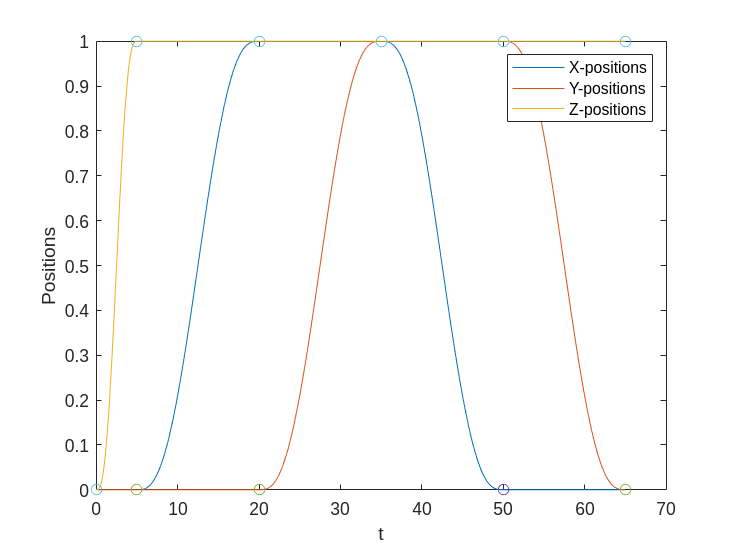

plot(tvec, q)
hold all
plot(tpts, wpts, 'o')
xlabel('t')
ylabel('Positions')
legend('X-positions','Y-positions','Z-positions')
hold off

You can also verify the actual positions in the 2-D plane. Plot the separate rows of the `q` vector and the waypoints as *x-* and *y- *positions.

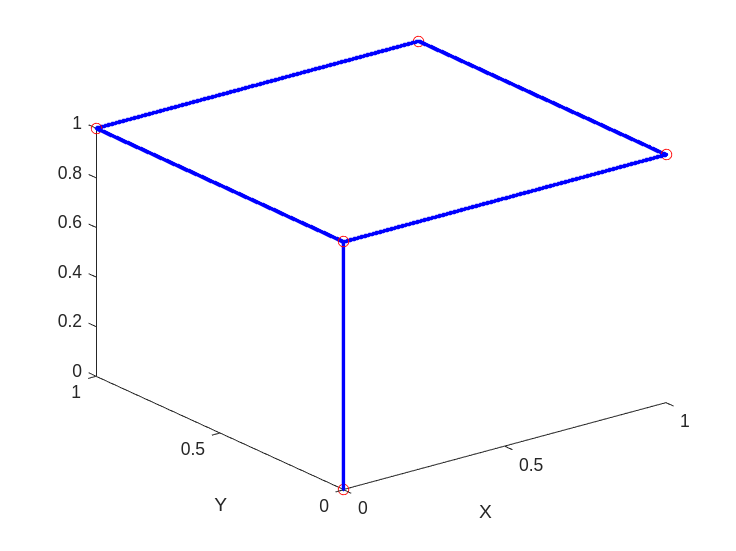

figure
plot3(q(1,:),q(2,:),q(3,:),'.b',wpts(1,:),wpts(2,:),wpts(3,:),'or')
xlabel('X')
ylabel('Y')

## Sliding Mode Control 

syms m g I_x I_y I_z I_p Omega 'real'
syms q x y z phi theta psi u1 u2 u3 u4 'real'
syms q_dot x_dot y_dot z_dot phi_dot theta_dot psi_dot 'real'
syms q_ddot x_ddot y_ddot z_ddot phi_ddot theta_ddot psi_ddot 'real'
q = [x;y;z;phi;theta;psi]

$$q = \left(\begin{array}{c} x\\ y\\ z\\ \varphi \\ \theta \\ \psi \end{array}\right)$$

u = [u1;u2;u3;u4]

$$u = \left(\begin{array}{c} u_{1}\\ u_{2}\\ u_{3}\\ u_{4} \end{array}\right)$$

Equations of Motion - Control Affine form

x_ddot = (cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi))*u1/m

$$x\_ddot = \frac{u_{1}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}$$

y_ddot = (cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))*u1/m

$$y\_ddot = -\frac{u_{1}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}$$

z_ddot = (cos(phi)*cos(theta))*u1/m -g

$$z\_ddot = \frac{u_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m}-g$$

phi_ddot = theta_dot*psi_dot*(I_y-I_z)/I_x - (I_p/I_x)*Omega*theta_dot + u2/I_x

$$phi\_ddot = \frac{u_{2}}{I_{x}}-\frac{I_{p}\,\Omega \,\dot{\theta }}{I_{x}}+\frac{\dot{\psi }\,\dot{\theta }\,\left(I_{y}-I_{z}\right)}{I_{x}}$$

theta_ddot = phi_dot*psi_dot*(I_z-I_x)/I_y + (I_p/I_y)*Omega*phi_dot + u3/I_y

$$theta\_ddot = \frac{u_{3}}{I_{y}}+\frac{I_{p}\,\Omega \,\dot{\varphi }}{I_{y}}-\frac{\dot{\varphi }\,\dot{\psi }\,\left(I_{x}-I_{z}\right)}{I_{y}}$$

psi_ddot = phi_dot*theta_dot*(I_x-I_y)/I_z + u4/I_z

$$psi\_ddot = \frac{u_{4}}{I_{z}}+\frac{\dot{\varphi }\,\dot{\theta }\,\left(I_{x}-I_{y}\right)}{I_{z}}$$

f_q_q_dot = [0;0;-g;theta_dot*psi_dot*(I_y-I_z)/I_x - (I_p/I_x)*Omega*theta_dot;phi_dot*psi_dot*(I_z-I_x)/I_y + (I_p/I_y)*Omega*phi_dot;phi_dot*theta_dot*(I_x-I_y)/I_z]

$$f\_q\_q\_dot = \left(\begin{array}{c} 0\\ 0\\ -g\\ \frac{\dot{\psi }\,\dot{\theta }\,\left(I_{y}-I_{z}\right)}{I_{x}}-\frac{I_{p}\,\Omega \,\dot{\theta }}{I_{x}}\\ \frac{I_{p}\,\Omega \,\dot{\varphi }}{I_{y}}-\frac{\dot{\varphi }\,\dot{\psi }\,\left(I_{x}-I_{z}\right)}{I_{y}}\\ \frac{\dot{\varphi }\,\dot{\theta }\,\left(I_{x}-I_{y}\right)}{I_{z}} \end{array}\right)$$

g_q_q_dot = [(cos(phi)*sin(theta)*cos(psi) + sin(phi)*sin(psi))/m,0,0,0;(cos(phi)*sin(theta)*sin(psi) - sin(phi)*cos(psi))/m,0,0,0;(cos(phi)*cos(theta))/m,0,0,0;0,1/I_x,0,0;0,0,1/I_y,0;0,0,0,1/I_z]

$$g\_q\_q\_dot = \left(\begin{array}{cccc} \frac{\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)}{m} & 0 & 0 & 0\\ -\frac{\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)}{m} & 0 & 0 & 0\\ \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m} & 0 & 0 & 0\\ 0 & \frac{1}{I_{x}} & 0 & 0\\ 0 & 0 & \frac{1}{I_{y}} & 0\\ 0 & 0 & 0 & \frac{1}{I_{z}} \end{array}\right)$$

q_ddot = f_q_q_dot+g_q_q_dot*u

$$q\_ddot = \left(\begin{array}{c} \frac{u_{1}\,\left(\sin\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\varphi \right)\,\cos\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}\\ -\frac{u_{1}\,\left(\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\sin\left(\psi \right)\,\sin\left(\theta \right)\right)}{m}\\ \frac{u_{1}\,\cos\left(\varphi \right)\,\cos\left(\theta \right)}{m}-g\\ \frac{u_{2}}{I_{x}}-\frac{I_{p}\,\Omega \,\dot{\theta }}{I_{x}}+\frac{\dot{\psi }\,\dot{\theta }\,\left(I_{y}-I_{z}\right)}{I_{x}}\\ \frac{u_{3}}{I_{y}}+\frac{I_{p}\,\Omega \,\dot{\varphi }}{I_{y}}-\frac{\dot{\varphi }\,\dot{\psi }\,\left(I_{x}-I_{z}\right)}{I_{y}}\\ \frac{u_{4}}{I_{z}}+\frac{\dot{\varphi }\,\dot{\theta }\,\left(I_{x}-I_{y}\right)}{I_{z}} \end{array}\right)$$

syms omega_1 omega_2 omega_3 omega_4 'real'
Omega = omega_1 - omega_2 + omega_3 - omega_4

$$Omega = \omega_{1}-\omega_{2}+\omega_{3}-\omega_{4}$$

syms F_x F_y k_p k_d x_d y_d x_dot_d y_dot_d x_ddot_d y_ddot_d theta_d phi_d 'real'
F_x = m*(-k_p*(x-x_d)-k_d*(x_dot-x_dot_d)+x_ddot_d)

$$F\_x = -m\,\left(k_{p}\,\left(x-x_{d}\right)-{\ddot{x}}_{d}+k_{d}\,\left(\dot{x}-{\dot{x}}_{d}\right)\right)$$

F_y = m*(-k_p*(y-y_d)-k_d*(y_dot-y_dot_d)+y_ddot_d)

$$F\_y = -m\,\left(k_{p}\,\left(y-y_{d}\right)-{\ddot{y}}_{d}+k_{d}\,\left(\dot{y}-{\dot{y}}_{d}\right)\right)$$

theta_d = asin(F_x/u1)

$$theta\_d = -\mathrm{asin}\left(\frac{m\,\left(k_{p}\,\left(x-x_{d}\right)-{\ddot{x}}_{d}+k_{d}\,\left(\dot{x}-{\dot{x}}_{d}\right)\right)}{u_{1}}\right)$$

phi_d = asin(-F_y/u1)

$$phi\_d = \mathrm{asin}\left(\frac{m\,\left(k_{p}\,\left(y-y_{d}\right)-{\ddot{y}}_{d}+k_{d}\,\left(\dot{y}-{\dot{y}}_{d}\right)\right)}{u_{1}}\right)$$

syms x_d y_d z_d phi_d theta_d psi_d x_dot_d y_dot_d z_dot_d phi_dot_d theta_dot_d psi_dot_d 'real'
e = [z-z_d;phi-phi_d;theta-theta_d;psi-psi_d]

$$e = \left(\begin{array}{c} z-z_{d}\\ \varphi -\varphi_{d}\\ \theta -\theta_{d}\\ \psi -\psi_{d} \end{array}\right)$$

e_dot = [z_dot-z_dot_d;phi_dot-phi_dot_d;theta_dot-theta_dot_d;psi_dot - psi_dot_d]

$$e\_dot = \left(\begin{array}{c} \dot{z}-{\dot{z}}_{d}\\ \dot{\varphi }-{\dot{\varphi }}_{d}\\ \dot{\theta }-{\dot{\theta }}_{d}\\ \dot{\psi }-{\dot{\psi }}_{d} \end{array}\right)$$

syms lambda 'real'
s = e_dot + lambda*e

$$s = \left(\begin{array}{c} \dot{z}-{\dot{z}}_{d}+\lambda \,\left(z-z_{d}\right)\\ \dot{\varphi }-{\dot{\varphi }}_{d}+\lambda \,\left(\varphi -\varphi_{d}\right)\\ \dot{\theta }-{\dot{\theta }}_{d}+\lambda \,\left(\theta -\theta_{d}\right)\\ \dot{\psi }-{\dot{\psi }}_{d}-\lambda \,\left(\psi_{d}-\psi \right) \end{array}\right)$$


s = subs(s,[psi_d,phi_dot_d,theta_dot_d,psi_dot_d],[0,0,0,0])

$$s = \left(\begin{array}{c} \dot{z}-{\dot{z}}_{d}+\lambda \,\left(z-z_{d}\right)\\ \dot{\varphi }+\lambda \,\left(\varphi -\varphi_{d}\right)\\ \dot{\theta }+\lambda \,\left(\theta -\theta_{d}\right)\\ \dot{\psi }+\lambda \,\psi \end{array}\right)$$

syms k rho s phi q_ddot_d u_r_1 u_r_2 u_r_3 u_r_4 z_ddot_d phi_ddot_d theta_ddot_d  psi_ddot_d 'real'
syms s_1 s_2 s_3 s_4 'real'
s = [s_1;s_2;s_3;s_4]

$$s = \left(\begin{array}{c} s_{1}\\ s_{2}\\ s_{3}\\ s_{4} \end{array}\right)$$

u_r = - (rho + k )*sign(s)

$$u\_r = \left(\begin{array}{c} -\mathrm{sign}\left(s_{1}\right)\,\left(k+\rho \right)\\ -\mathrm{sign}\left(s_{2}\right)\,\left(k+\rho \right)\\ -\mathrm{sign}\left(s_{3}\right)\,\left(k+\rho \right)\\ -\mathrm{sign}\left(s_{4}\right)\,\left(k+\rho \right) \end{array}\right)$$


q_ddot_d = [z_ddot_d;phi_ddot_d;theta_ddot_d;psi_ddot_d]

$$q\_ddot\_d = \left(\begin{array}{c} {\ddot{z}}_{d}\\ {\ddot{\varphi }}_{d}\\ {\ddot{\theta }}_{d}\\ {\ddot{\psi }}_{d} \end{array}\right)$$

u = g_q_q_dot(3:6,:)*(-1* f_q_q_dot(3:6) + q_ddot_d - lambda*e_dot + u_r)

$$u = \left(\begin{array}{c} \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(g+{\ddot{z}}_{d}-\lambda \,\left(\dot{z}-{\dot{z}}_{d}\right)-\mathrm{sign}\left(s_{1}\right)\,\left(k+\rho \right)\right)}{m}\\ -\frac{\lambda \,\left(\dot{\varphi }-{\dot{\varphi }}_{d}\right)-{\ddot{\varphi }}_{d}+\mathrm{sign}\left(s_{2}\right)\,\left(k+\rho \right)-\frac{I_{p}\,\Omega \,\dot{\theta }}{I_{x}}+\frac{\dot{\psi }\,\dot{\theta }\,\left(I_{y}-I_{z}\right)}{I_{x}}}{I_{x}}\\ -\frac{\lambda \,\left(\dot{\theta }-{\dot{\theta }}_{d}\right)-{\ddot{\theta }}_{d}+\mathrm{sign}\left(s_{3}\right)\,\left(k+\rho \right)+\frac{I_{p}\,\Omega \,\dot{\varphi }}{I_{y}}-\frac{\dot{\varphi }\,\dot{\psi }\,\left(I_{x}-I_{z}\right)}{I_{y}}}{I_{y}}\\ -\frac{\lambda \,\left(\dot{\psi }-{\dot{\psi }}_{d}\right)-{\ddot{\psi }}_{d}+\mathrm{sign}\left(s_{4}\right)\,\left(k+\rho \right)+\frac{\dot{\varphi }\,\dot{\theta }\,\left(I_{x}-I_{y}\right)}{I_{z}}}{I_{z}} \end{array}\right)$$

u = subs(u,[psi_d,phi_dot_d,theta_dot_d,psi_dot_d,phi_ddot_d,theta_ddot_d,psi_ddot_d,rho],[0,0,0,0,0,0,0,0])

$$u = \left(\begin{array}{c} \frac{\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\left(g+{\ddot{z}}_{d}-\lambda \,\left(\dot{z}-{\dot{z}}_{d}\right)-k\,\mathrm{sign}\left(s_{1}\right)\right)}{m}\\ -\frac{\lambda \,\dot{\varphi }+k\,\mathrm{sign}\left(s_{2}\right)-\frac{I_{p}\,\Omega \,\dot{\theta }}{I_{x}}+\frac{\dot{\psi }\,\dot{\theta }\,\left(I_{y}-I_{z}\right)}{I_{x}}}{I_{x}}\\ -\frac{\lambda \,\dot{\theta }+k\,\mathrm{sign}\left(s_{3}\right)+\frac{I_{p}\,\Omega \,\dot{\varphi }}{I_{y}}-\frac{\dot{\varphi }\,\dot{\psi }\,\left(I_{x}-I_{z}\right)}{I_{y}}}{I_{y}}\\ -\frac{\lambda \,\dot{\psi }+k\,\mathrm{sign}\left(s_{4}\right)+\frac{\dot{\varphi }\,\dot{\theta }\,\left(I_{x}-I_{y}\right)}{I_{z}}}{I_{z}} \end{array}\right)$$